# Visualizing Cricket Statistics

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code loads and plots the data.

stats = readtable("../data/cricketers.csv");
% Show the data
stats

stats = 275×3 table
           Name           BattingAvg    BowlingAvg
    __________________    __________    __________

    {'Bob Willis'    }       11.5          25.2   
    {'Tony Greig'    }      40.43          32.2   
    {'Chris Old'     }      14.82         28.11   
    {'Mike Hendrick' }        6.4         25.83   
    {'Graham Gooch'  }      42.58         46.47   
    {'Phil Edmonds'  }       17.5         34.18   
    {'Geoff Miller'  }       25.8         30.98   
    {'John Lever'    }      11.76         26.72   
    {'Ian Botham'    }      33.54          28.4   
    {'John Emburey'  }      22.53          38.4   
    {'Graham Dilley' }      13.35         29.76   
    {'Derek Pringle' }       15.1         35.97   
    {'Neil Foster'   }      11.73         32.85   
    {'Phil DeFreitas'}      14.82         33.57   
    {'Angus Fraser'  }       7.46         27.32   
    {'Devo

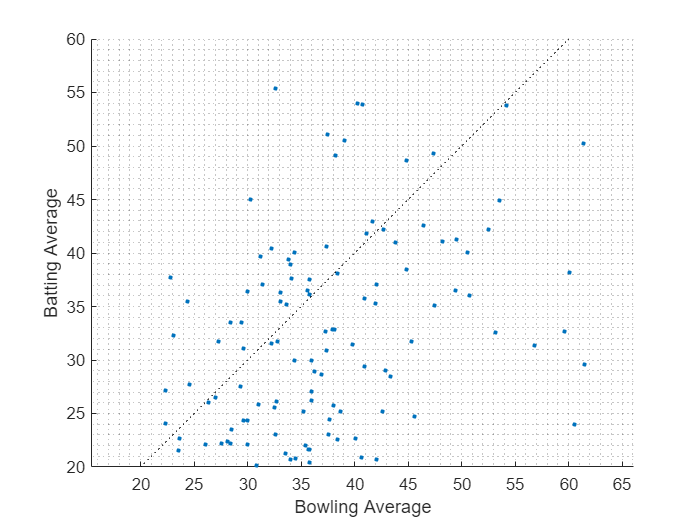

% Extract data into separate variables
x = stats.BowlingAvg;
y = stats.BattingAvg;
name = stats.Name;
% Make a scatter plot of averages
scatter(x,y,6,"filled")
hold on
plot([20 60],[20 60],"k:")
hold off
xlim([20 60])
xlabel("Bowling Average")
ylim([20 60])
ylabel("Batting Average")
axis equal
grid minor

## Task 1

higherbat = (stats.BattingAvg > stats.BowlingAvg);

## Task 2

allround = stats(higherbat,:)

allround = 36×3 table
           Name           BattingAvg    BowlingAvg
    __________________    __________    __________

    {'Tony Greig'    }      40.43          32.2   
    {'Ian Botham'    }      33.54          28.4   
    {'Joe Root'      }      48.68         44.81   
    {'Ben Stokes'    }      37.04         31.38   
    {'Greg Chappell' }      53.86          40.7   
    {'Allan Border'  }      50.56          39.1   
    {'Steve Waugh'   }      51.06         37.44   
    {'Mark Waugh'    }      41.81         41.16   
    {'Simon Katich'  }      45.03         30.23   
    {'Andrew Symonds'}      40.61         37.33   
    {'Michael Clarke'}       49.1         38.19   
    {'Shane Watson'  }      35.19         33.68   
    {'Hansie Cronje' }      36.41         29.95   
    {'Brian McMillan'}      39.36         33.82   
    {'Shaun Pollock' }      32.31         23.11   
    {'Ja

## Task 3

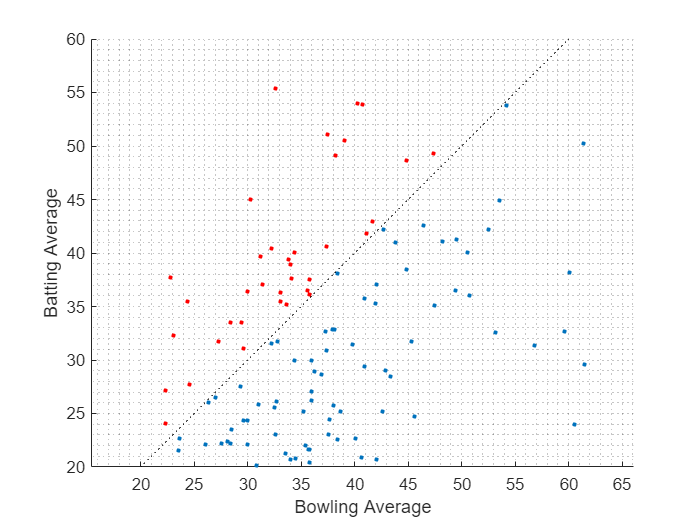

hold on
scatter(allround.BowlingAvg,allround.BattingAvg,6,"r","filled")
hold off

## Task 4

bat = y > 50;
bowl = x < 25;

## Task 5

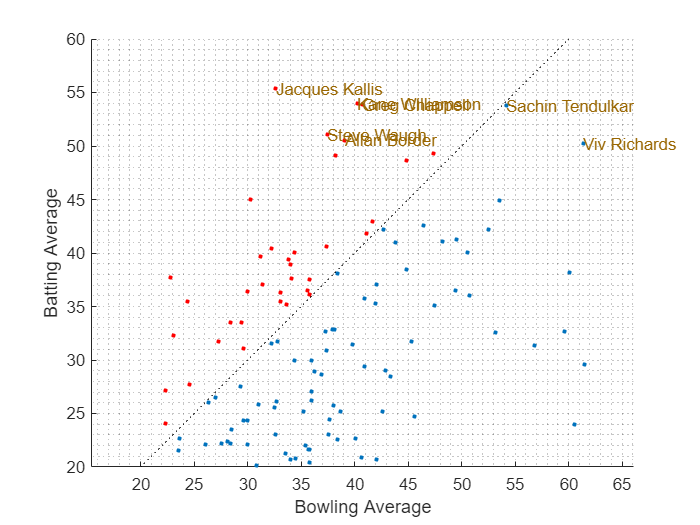

text(x(bat),y(bat),name(bat),"Color",[0.6 0.4 0])

## Task 6

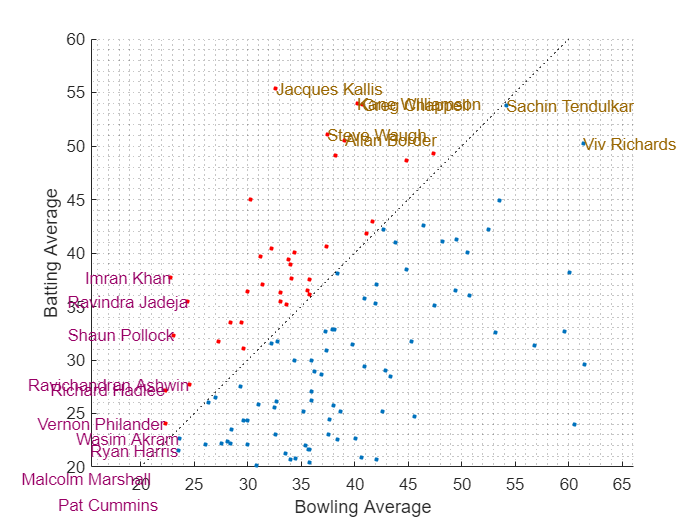

text(x(bowl),y(bowl),name(bowl),"Color",[0.6 0 0.4],"HorizontalAlignment","right")

## Task 7

idx = higherbat & ~(bat|bowl);
numAR = nnz(idx)

numAR = 25